%======================================================================
% ECSE 443 - Assignment 3
% Author ----- Tristan Bouchard
% Student ID - 260747124
% Submitted -- Sunday, March 17, 2019 at 5pm.
%======================================================================
close all
clear all
addpath('./Functions/');
% Use the long format for more precision
format long


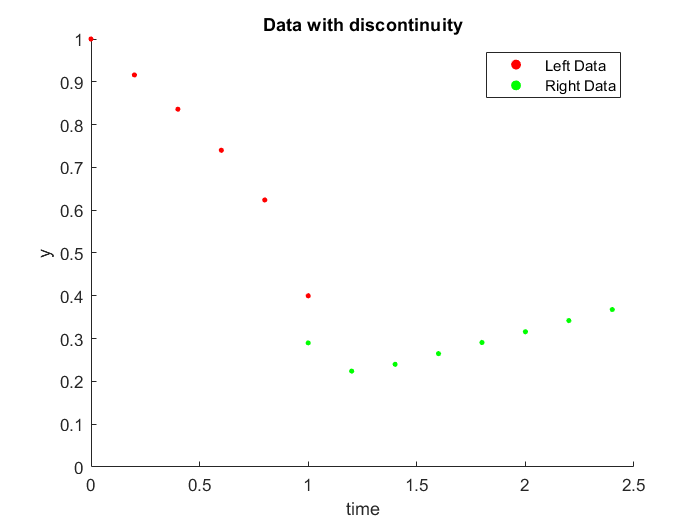

%======================================================================
% Question 1 - Interpolation at f(0.23) (12 Marks)
%======================================================================

% Import data and plot points, to get an idea of what we have
timeLeft = [0:0.2:1]';
dataLeft = [1 0.916 0.836 0.74 0.624 0.4]';
timeRight = [1:0.2:2.4]';
dataRight = [0.29 0.224 0.24 0.265 0.291 0.316 0.342 0.368]';
dataLeft = [timeLeft dataLeft];
dataRight = [timeRight dataRight];

legendTitles = ["Left Data", "Right Data"];
plotTitle = "Data with discontinuity";
yScale = [0 1];

% Plot the data points
plotData(dataLeft, dataRight, "No Data", legendTitles, plotTitle, yScale);

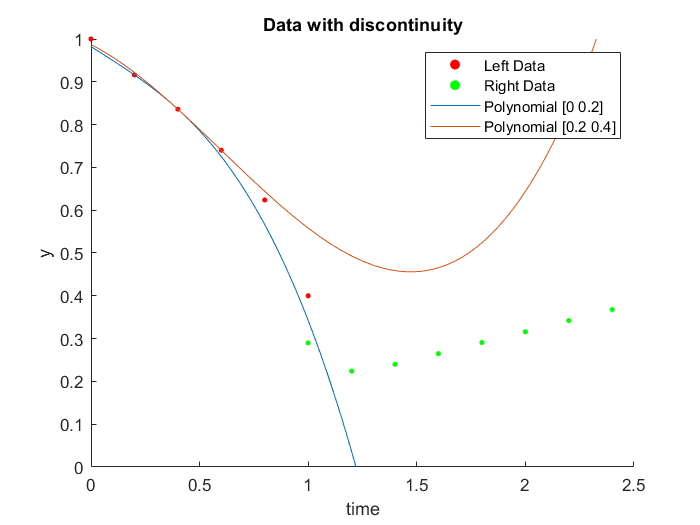

%======================================================================
% Question 1.a) - Cubic Splines (4 Marks)
%======================================================================
close all
point1 = [dataLeft(2,1) dataLeft(2,2)];
point2 = [dataLeft(3,1) dataLeft(3,2)];
point3 = [dataLeft(4,1) dataLeft(4,2)];
coeff = cubicSpline(point1, point2, point3);

t=[0:0.01:2.5];
func1 = coeff(1,1) + coeff(1,2)*t + coeff(1,3)*t.^2 + coeff(1,4)*t.^3;
func2 = coeff(2,1) + coeff(2,2)*t + coeff(2,3)*t.^2 + coeff(2,4)*t.^3;

plotData(dataLeft, dataRight, "No Data", legendTitles, plotTitle, yScale);
hold on
plot(t, func1);
plot(t, func2);
legend("Left Data", "Right Data", "Polynomial [0 0.2]", "Polynomial [0.2 0.4]")
hold off


% Using the computed coefficients for the first interval from [0.2 0.4] we
% can obtain the exact value of f(0.23)

syms x;
f(x) = coeff(1,1) + coeff(1,2)*x + coeff(1,3)*x.^2 + coeff(1,4)*x.^3;
result = double(f(0.23));
disp("The computed value of the function at t = 0.23 using cubic splines = ")

The computed value of the function at t = 0.23 using cubic splines = 


disp(result);

   0.905293214285714



%======================================================================
% Question 1.b) - Lagrange Polynomial (4 Marks)
%======================================================================

lagrangeInterpVal = lagrangianInterpolation(0.23, dataLeft);
disp("The interpolated value for t = 0.23 using the Lagrangian" +  newline + "Polynomial " + ...
    "Interpolation method = ");

The interpolated value for t = 0.23 using the Lagrangian
Polynomial Interpolation method = 


vpa(lagrangeInterpVal)

$$ans = 0.90505882109375002109175056830281$$

%======================================================================
% Question 1.c) - Newton Polynomial Interpolation (4 Marks)
%======================================================================

newtonCoeff = newtonCoefficients(dataLeft);
newtonInterpVal = newtonInterpolation(0.23, newtonCoeff, dataLeft);

disp("Interpolated value of f(0.23) using Newton interpolation = ");

Interpolated value of f(0.23) using Newton interpolation = 


disp(newtonInterpVal);

   0.905058821093750



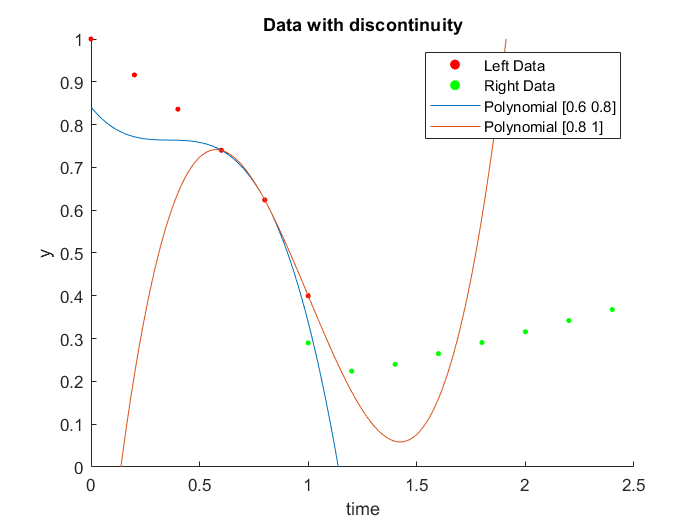

%======================================================================
% Question 2.a) - Cubic Splines Interpolation (4 Marks)
%======================================================================
close all
point1 = [dataLeft(4,1) dataLeft(4,2)];
point2 = [dataLeft(5,1) dataLeft(5,2)];
point3 = [dataLeft(6,1) dataLeft(6,2)];
coeff = cubicSpline(point1, point2, point3);

t=[0:0.01:2.5];
func1 = coeff(1,1) + coeff(1,2)*t + coeff(1,3)*t.^2 + coeff(1,4)*t.^3;
func2 = coeff(2,1) + coeff(2,2)*t + coeff(2,3)*t.^2 + coeff(2,4)*t.^3;

plotData(dataLeft, dataRight, "No Data", legendTitles, plotTitle, yScale);
hold on
plot(t, func1);
plot(t, func2);
legend("Left Data", "Right Data", "Polynomial [0.6 0.8]", "Polynomial [0.8 1]")
hold off


% Using the computed coefficients for the first interval from [0.6 0.8] we
% can obtain the exact value of f(0.78)

syms x;
f(x) = coeff(1,1) + coeff(1,2)*x + coeff(1,3)*x.^2 + coeff(1,4)*x.^3;
result = double(f(0.78));
disp("The computed value of the function at t = 0.78 using cubic splines = ")

The computed value of the function at t = 0.78 using cubic splines = 


disp(result);

   0.641964285714286



%======================================================================
% Question 2.b) - Lagrangian Interpolation (4 Marks)
%======================================================================
lagrangeInterpVal = lagrangianInterpolation(0.78, dataLeft);
disp("The interpolated value for t = 0.23 using the Lagrangian" +  newline + "Polynomial " + ...
    "Interpolation method = ");

The interpolated value for t = 0.23 using the Lagrangian
Polynomial Interpolation method = 


vpa(lagrangeInterpVal)

$$ans = 0.63789507499999997808259877274395$$

%======================================================================
% Question 2.c) - Newton Polynomial Interpolation (4 Marks)
%======================================================================

newtonCoeff = newtonCoefficients(dataLeft);
newtonInterpVal = newtonInterpolation(0.78, newtonCoeff, dataLeft);

disp("Interpolated value of f(0.78) using Newton interpolation = ");

Interpolated value of f(0.78) using Newton interpolation = 


disp(newtonInterpVal);

   0.637895075000000



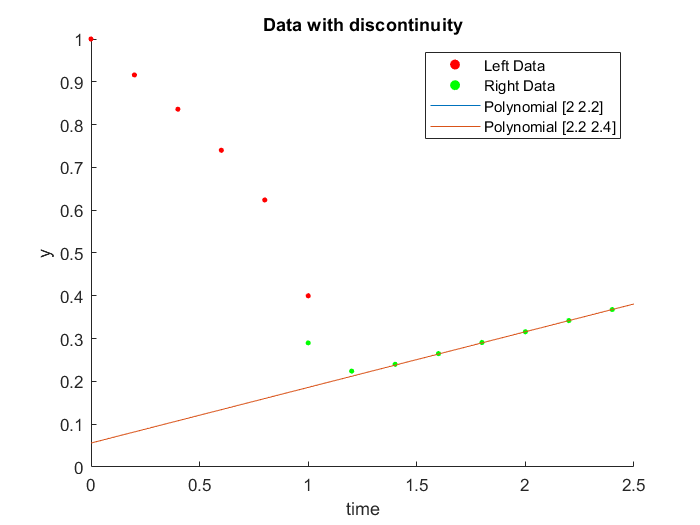

%======================================================================
% Question 3 - Cubic Spline extrapolation (4 Marks)
%======================================================================

% Using the last cubic spline equation computed on the interval [2.2 2.4]
close all
point1 = [dataRight(6,1) dataRight(6,2)];
point2 = [dataRight(7,1) dataRight(7,2)];
point3 = [dataRight(8,1) dataRight(8,2)];
coeff = cubicSpline(point1, point2, point3);

t=[0:0.01:2.5];
func1 = coeff(1,1) + coeff(1,2)*t + coeff(1,3)*t.^2 + coeff(1,4)*t.^3;
func2 = coeff(2,1) + coeff(2,2)*t + coeff(2,3)*t.^2 + coeff(2,4)*t.^3;

plotData(dataLeft, dataRight, "No Data", legendTitles, plotTitle, yScale);
hold on
plot(t, func1);
plot(t, func2);
legend("Left Data", "Right Data", "Polynomial [2 2.2]", "Polynomial [2.2 2.4]")
hold off


% Using the computed coefficients for the first interval from [0.6 0.8] we
% can obtain the exact value of f(0.78)

syms x;
f(x) = coeff(2,1) + coeff(2,2)*x + coeff(2,3)*x.^2 + coeff(2,4)*x.^3;
result = double(f(3));
disp("The computed value of the function at t = 0.78 using cubic splines = ")

The computed value of the function at t = 0.78 using cubic splines = 


disp(result);

   0.445999999999999

